# **Name - Vinay Patil**

# **Net ID - vpatil3**

# **Question (1)**

## **1 (a)**

ImageData = imread('img_001.ppm');

Dimensions = size(ImageData)

Dimensions =    605   700     3


**The Dimensions (Rows, Columns, Pages) represent Height, Width and  No.of.Color Channels(RGB) of the image respectively**

LargestIntensity = max(ImageData(:))

LargestIntensity = uint8
255

SmallestIntensity = min(ImageData(:))

SmallestIntensity = uint8
0

NoOfPixels = Dimensions(1) * Dimensions(2)

NoOfPixels = 423500

## **1 (b)**

First5RowValues = ImageData(1:5,1,1)

First5RowValues = 5×1 uint8 column vector
   11
   10
    9
   10
   10


DivideBy3 = First5RowValues./3

DivideBy3 = 5×1 uint8 column vector
   4
   3
   3
   3
   3


**The numbers are rounded of to the next integer and hence loose precision, this is because of the integer division (First5RowValues is an uinit8 column vector)**

DoublePrecisionImage = double(ImageData);
NewFirst5RowValues = DoublePrecisionImage(1:5,1,1)

NewFirst5RowValues =     11
    10
     9
    10
    10


NewDivideBy3 = NewFirst5RowValues./3

NewDivideBy3 =     3.6667
    3.3333
    3.0000
    3.3333
    3.3333


**Yes, the conversion from int to double fixed the issue, because now the division is precise as double numbers are allowed (NewFirst5RowValues is of class double)**

## **1 (c)**

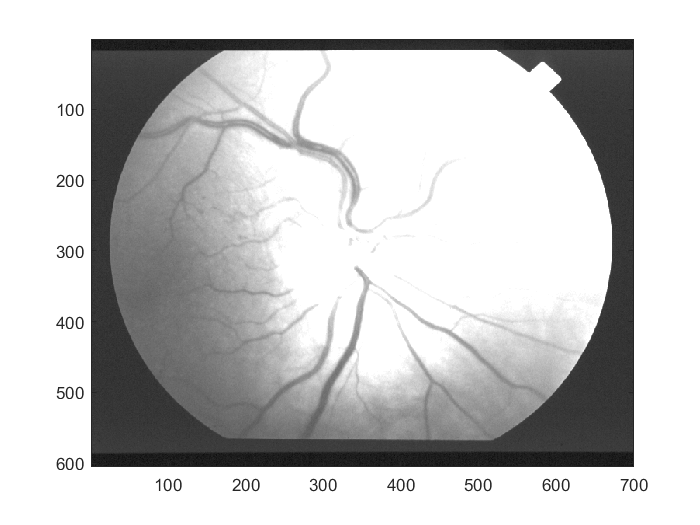

image(DoublePrecisionImage(:,:,2));colormap('gray')

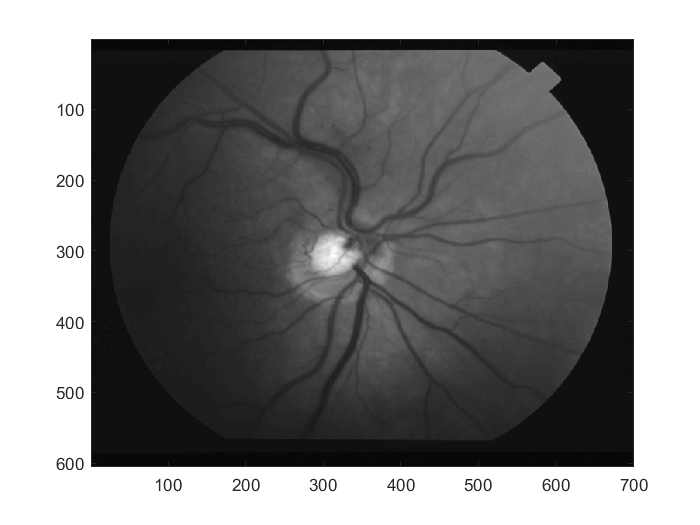

imagesc(DoublePrecisionImage(:,:,2))

**MATLAB colormaps have 64 colors by default and the image function doesn't scale values but instead clips the out of range values. Where as the imagesc function does automatic scaling, which allows to use the full colormap. However, If we explicitly specify colormaps to use 256 colors - colormap('gray(256)'), the image function gives comparable results to imagesc.**

# **Question (2)**

## **2 (a)**

FilteredImage33 = zeros(Dimensions(1),Dimensions(2));
for x = 2:Dimensions(1)-1
    for y = 2:Dimensions(2)-1
        Neighborhood = DoublePrecisionImage(x-1:x+1,y-1:y+1,2);
        FilteredImage33(x,y) = mean(Neighborhood(:));      
    end
end

FilteredImage3x3 = FilteredImage33(1:10,1:10)

FilteredImage3x3 =          0         0         0         0         0         0         0         0         0         0
         0    8.5556    8.0000    8.3333    7.8889    8.2222    8.2222    9.0000    8.7778    8.7778
         0    8.8889    8.1111    8.1111    7.5556    8.0000    8.3333    8.8889    8.4444    8.2222
         0    8.1111    7.5556    8.0000    7.8889    8.2222    8.5556    8.6667    8.3333    7.8889
         0    8.1111    7.7778    8.1111    8.0000    8.2222    8.4444    8.3333    8.0000    7.7778
         0    7.5556    7.7778    8.3333    8.2222    8.1111    8.2222    8.0000    7.8889    8.0000
         0    8.1111    8.2222    8.6667    8.2222    8.3333    8.2222    8.2222    8.1111    8.1111
         0    8.1111    8.2222    8.7778    8.4444    8.3333    8.3333    8.4444    8.6667    8.2222
         0    8.1111    8.0000    8.5556    8.6667    8.7778    9.0000    9.0000    9.1111    8.4444
         0    7.6667    7.6667    8.0000    8.3333    8.4444    9.0000  

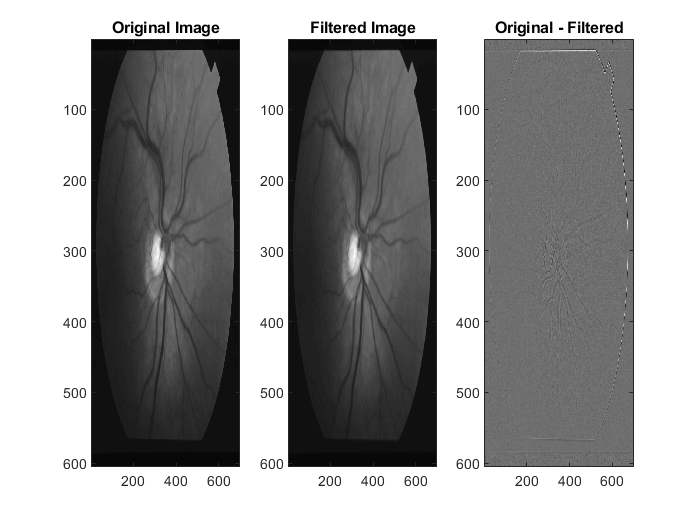

subplot(1,3,1)
imagesc(DoublePrecisionImage(:,:,2))
title('Original Image')
subplot(1,3,2)
imagesc(FilteredImage33)
title('Filtered Image')
subplot(1,3,3)
imagesc(DoublePrecisionImage(:,:,2)-FilteredImage33)
title('Original - Filtered')

## **2 (b)**

FilteredImage99 = zeros(Dimensions(1),Dimensions(2));
for x = 5:Dimensions(1)-4
    for y = 5:Dimensions(2)-4
        Neighborhood = DoublePrecisionImage(x-4:x+4,y-4:y+4,2);
        FilteredImage99(x,y) = mean(Neighborhood(:));      
    end
end

FilteredImage9x9 = FilteredImage99(1:10,1:10)

FilteredImage9x9 =          0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    8.3210    8.2469    8.3333    8.2963    8.2469    8.2346
         0         0         0         0    8.3210    8.2469    8.3580    8.3210    8.2469    8.2099
         0         0         0         0    8.2222    8.1975    8.2963    8.2716    8.1975    8.1728
         0         0         0         0    8.1358    8.1605    8.2469    8.2716    8.1852    8.1481
         0         0         0         0    8.1605    8.1852    8.2963    8.3086    8.2222    8.1728
         0         0         0         0    8.2099    8.2099    8.2963  

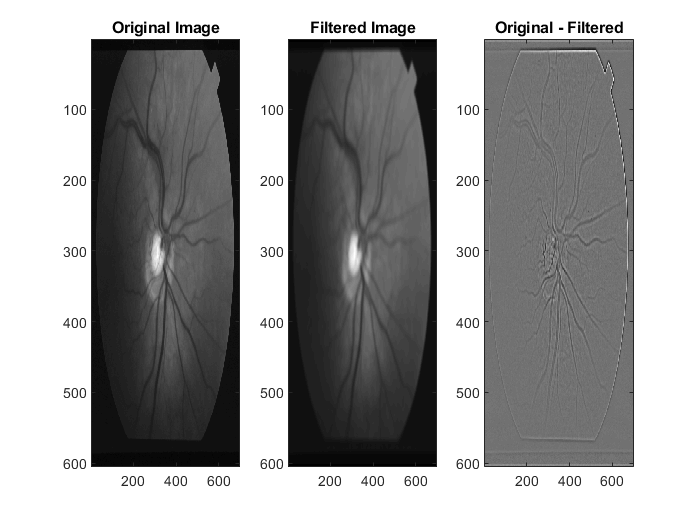

figure
colormap('gray')
subplot(1,3,1)
imagesc(DoublePrecisionImage(:,:,2))
title('Original Image')
subplot(1,3,2)
imagesc(FilteredImage99)
title('Filtered Image')
subplot(1,3,3)
imagesc(DoublePrecisionImage(:,:,2)-FilteredImage99)
title('Original - Filtered')

## **2 (c)**

**Gradiant disappears after subtraction and small white dots are introduced(Which I observed when I explicitly subtracted the original from the filtered image), also a border was introducted mainly because of the 0's at the edges of our filtered image.**

# **Question (3)**

## **3**

ResizedImage = zeros();
x1 = 0;
y1 = 0;
for x = 3:5:Dimensions(1)-2
    x1 = x1 + 1;
    for y = 3:5:Dimensions(2)-2
        y1 = y1 + 1;
        Neighborhood = DoublePrecisionImage(x-2:x+2,y-2:y+2,2);
        ResizedImage(x1,y1) = mean(Neighborhood(:));      
    end
    y1= 0;
    
end

ResizedImageDimensions = size(ResizedImage)

ResizedImageDimensions =    121   140


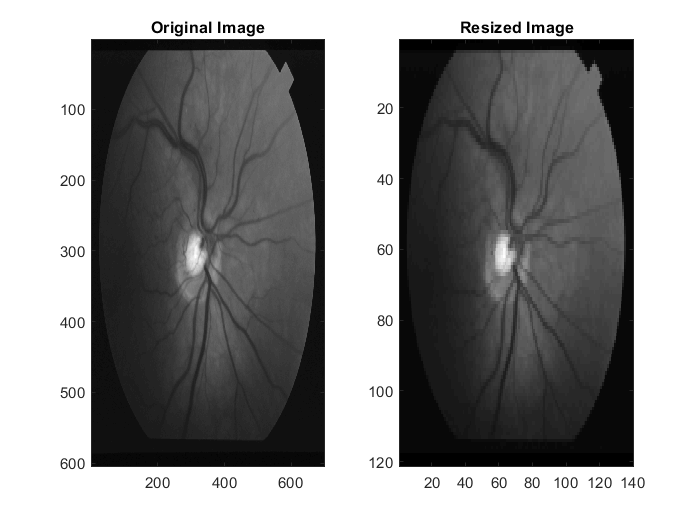

figure
colormap('gray')
subplot(1,2,1)
imagesc(DoublePrecisionImage(:,:,2))
title('Original Image')
subplot(1,2,2)
imagesc(ResizedImage)
title('Resized Image')